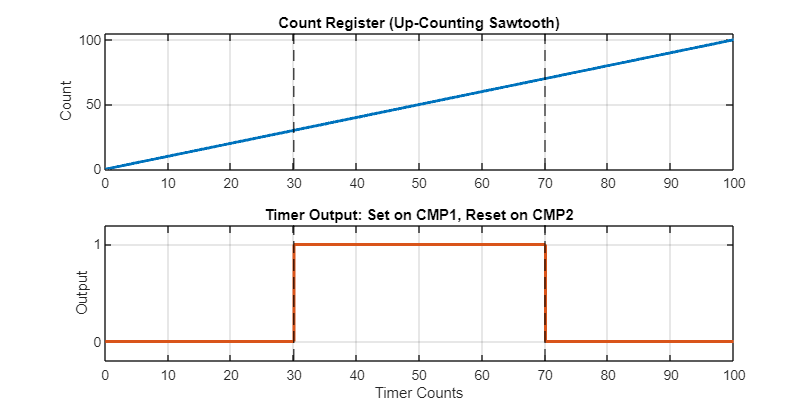

% Timer timing diagram for MCU datasheet-style plots
clear; clc; close all;

% Parameters
PER  = 100;   % Full-scale count
CMP1 = 30;    % Set point
CMP2 = 70;    % Reset point
N    = 1000;  % Plot resolution

% Time axis over one full timer cycle
t = linspace(0, PER, N);

% Count register: up-count sawtooth
count = t;

% Timer output: set at CMP1, reset at CMP2
out = zeros(size(t));
out(t >= CMP1 & t < CMP2) = 1;

% Compare event times for vertical lines
cmp_points = [CMP1 CMP2];

figure('Color','w','Position',[100 100 1000 500]);

% Count register waveform
subplot(2,1,1);
plot(t, count, 'LineWidth', 2, 'Color', [0 0.45 0.74]); hold on;
for x = cmp_points
    xline(x, '--k', 'LineWidth', 1);
end
ylim([-0.05 PER*1.05]);
xlim([0 PER]);
ylabel('Count');
title('Count Register (Up-Counting Sawtooth)');
grid on;

% Timer output waveform
subplot(2,1,2);
stairs(t, out, 'LineWidth', 2, 'Color', [0.85 0.33 0.10]); hold on;
for x = cmp_points
    xline(x, '--k', 'LineWidth', 1);
end
ylim([-0.2 1.2]);
xlim([0 PER]);
yticks([0 1]);
ylabel('Output');
xlabel('Timer Counts');
title('Timer Output: Set on CMP1, Reset on CMP2');
grid on;